%% Tuned Filter Bank CSP + SVM Classifier
% 3-class EEG classification:
% 1 = Left
% 2 = Right
% 3 = Rest
%
% This script uses:
% Filter Bank CSP features + feature selection + SVM hyperparameter tuning
%
% It also saves:
% Trained SVM model
% CSP filters
% Best settings
% Predicted robot commands

clear; clc; close all;

%% Load combined epochs

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';

dataFile = fullfile(basePath, 'Outputs', 'Filtered data', 'combined_epochs.mat');

if ~isfile(dataFile)
    error("combined_epochs.mat not found. Check your basePath or output folder.");
end

load(dataFile);

% Expected variables:
% all_left  -> channels x samples x epochs
% all_right -> channels x samples x epochs
% all_rest  -> channels x samples x epochs

sfreq = 160;

fprintf("Left epochs: %d\n", size(all_left,3));

Left epochs: 230


fprintf("Right epochs: %d\n", size(all_right,3));

Right epochs: 220


fprintf("Rest epochs: %d\n", size(all_rest,3));

Rest epochs: 420



%% Balance the three classes
rng(42);
n = min([size(all_left,3), size(all_right,3), size(all_rest,3)]);
idx_left  = randperm(size(all_left,3), n);
idx_right = randperm(size(all_right,3), n);
idx_rest  = randperm(size(all_rest,3), n);

X = cat(3, ...
    all_left(:,:,idx_left), ...
    all_right(:,:,idx_right), ...
    all_rest(:,:,idx_rest));

% Labels:
% 1 = Left
% 2 = Right
% 3 = Rest
y = [ones(n,1); 2*ones(n,1); 3*ones(n,1)];

fprintf("\nBalanced dataset:\n");


Balanced dataset:


fprintf("Channels: %d\n", size(X,1));

Channels: 64


fprintf("Samples per epoch: %d\n", size(X,2));

Samples per epoch: 640


fprintf("Total epochs: %d\n", size(X,3));

Total epochs: 660


fprintf("Epochs per class: %d\n", n);

Epochs per class: 220



%% Train-test split

cv = cvpartition(y, 'HoldOut', 0.2);

trainIdx = training(cv);
testIdx  = test(cv);

X_train = X(:,:,trainIdx);
X_test  = X(:,:,testIdx);

y_train = y(trainIdx);
y_test  = y(testIdx);

fprintf("\nTraining epochs: %d\n", length(y_train));


Training epochs: 528


fprintf("Testing epochs: %d\n", length(y_test));

Testing epochs: 132



%% Define Filter Bank frequency bands

bands = [
    8 12;
    12 16;
    16 20;
    20 24;
    24 30
];

% Number of CSP filter pairs
% m = 2 means first 2 and last 2 CSP filters are selected per class
m = 2;

feat_train_all = [];
feat_test_all  = [];

% This stores CSP filters for each frequency band
% Needed later for robot/new EEG prediction
W_bank = cell(size(bands,1), 1);

fprintf("\nStarting Filter Bank CSP feature extraction...\n");


Starting Filter Bank CSP feature extraction...



%% Extract Filter Bank CSP features

for b = 1:size(bands,1)

    lowF = bands(b,1);
    highF = bands(b,2);

    fprintf("\nProcessing band %d-%d Hz...\n", lowF, highF);

    % Step 1: Bandpass filter training and testing epochs
    X_train_band = bandpass_epochs(X_train, sfreq, lowF, highF);
    X_test_band  = bandpass_epochs(X_test, sfreq, lowF, highF);

    % Step 2: Train multiclass CSP using training data only
    W_all = train_multiclass_csp(X_train_band, y_train, m);

    % Save CSP filters for this frequency band
    W_bank{b} = W_all;

    % Step 3: Extract CSP log-variance features
    feat_train_band = extract_multiclass_csp_features(X_train_band, W_all);
    feat_test_band  = extract_multiclass_csp_features(X_test_band, W_all);

    % Step 4: Combine features from all bands
    feat_train_all = [feat_train_all, feat_train_band];
    feat_test_all  = [feat_test_all, feat_test_band];

end


Processing band 8-12 Hz...


CSP filters trained for class 1 vs rest
CSP filters trained for class 2 vs rest
CSP filters trained for class 3 vs rest



Processing band 12-16 Hz...


CSP filters trained for class 1 vs rest
CSP filters trained for class 2 vs rest
CSP filters trained for class 3 vs rest



Processing band 16-20 Hz...


CSP filters trained for class 1 vs rest
CSP filters trained for class 2 vs rest
CSP filters trained for class 3 vs rest



Processing band 20-24 Hz...


CSP filters trained for class 1 vs rest
CSP filters trained for class 2 vs rest
CSP filters trained for class 3 vs rest



Processing band 24-30 Hz...


CSP filters trained for class 1 vs rest
CSP filters trained for class 2 vs rest
CSP filters trained for class 3 vs rest



fprintf("\nFinal FBCSP training feature size: %d x %d\n", ...
    size(feat_train_all,1), size(feat_train_all,2));


Final FBCSP training feature size: 528 x 60



fprintf("Final FBCSP testing feature size: %d x %d\n", ...
    size(feat_test_all,1), size(feat_test_all,2));

Final FBCSP testing feature size: 132 x 60



fprintf("\nEach EEG epoch is represented using %d FBCSP features.\n", ...
    size(feat_train_all,2));


Each EEG epoch is represented using 60 FBCSP features.



%% Feature selection

fprintf("\nRanking features using training data only...\n");


Ranking features using training data only...



[rankedIdx, featureScores] = rank_features(feat_train_all, y_train);

totalFeatures = size(feat_train_all,2);

topKList = [10 20 30 40 totalFeatures];
topKList = unique(topKList);
topKList = topKList(topKList <= totalFeatures);

%% SVM hyperparameter tuning

kernelList = {'linear', 'rbf'};
codingList = {'onevsone', 'onevsall'};
CList = [0.1 1 10];

bestCVAccuracy = 0;
bestSettings = struct();

topK_col = [];
kernel_col = {};
coding_col = {};
C_col = [];
cvAccuracy_col = [];

fprintf("\nStarting SVM tuning...\n");


Starting SVM tuning...



for kIdx = 1:length(topKList)

    topK = topKList(kIdx);
    selectedFeatures = rankedIdx(1:topK);

    Xtr = feat_train_all(:, selectedFeatures);

    for cIdx = 1:length(CList)

        C = CList(cIdx);

        for kernelIdx = 1:length(kernelList)

            kernelName = kernelList{kernelIdx};

            for codeIdx = 1:length(codingList)

                codingName = codingList{codeIdx};

                if strcmp(kernelName, 'linear')

                    template = templateSVM( ...
                        'KernelFunction', 'linear', ...
                        'BoxConstraint', C, ...
                        'Standardize', true);

                else

                    template = templateSVM( ...
                        'KernelFunction', 'rbf', ...
                        'KernelScale', 'auto', ...
                        'BoxConstraint', C, ...
                        'Standardize', true);

                end

                % 5-fold cross-validation on training data only
                cvModel = fitcecoc( ...
                    Xtr, y_train, ...
                    'Learners', template, ...
                    'Coding', codingName, ...
                    'KFold', 5);

                cvLoss = kfoldLoss(cvModel);
                cvAccuracy = (1 - cvLoss) * 100;

                fprintf("TopK=%d | Kernel=%s | Coding=%s | C=%.1f | CV Accuracy=%.2f%%\n", ...
                    topK, kernelName, codingName, C, cvAccuracy);

                topK_col = [topK_col; topK];
                kernel_col = [kernel_col; {kernelName}];
                coding_col = [coding_col; {codingName}];
                C_col = [C_col; C];
                cvAccuracy_col = [cvAccuracy_col; cvAccuracy];

                if cvAccuracy > bestCVAccuracy

                    bestCVAccuracy = cvAccuracy;

                    bestSettings.topK = topK;
                    bestSettings.selectedFeatures = selectedFeatures;
                    bestSettings.kernelName = kernelName;
                    bestSettings.codingName = codingName;
                    bestSettings.C = C;

                end
            end
        end
    end
end

TopK=10 | Kernel=linear | Coding=onevsone | C=0.1 | CV Accuracy=60.80%
TopK=10 | Kernel=linear | Coding=onevsall | C=0.1 | CV Accuracy=61.74%
TopK=10 | Kernel=rbf | Coding=onevsone | C=0.1 | CV Accuracy=59.47%
TopK=10 | Kernel=rbf | Coding=onevsall | C=0.1 | CV Accuracy=67.05%
TopK=10 | Kernel=linear | Coding=onevsone | C=1.0 | CV Accuracy=61.36%
TopK=10 | Kernel=linear | Coding=onevsall | C=1.0 | CV Accuracy=59.09%
TopK=10 | Kernel=rbf | Coding=onevsone | C=1.0 | CV Accuracy=66.29%
TopK=10 | Kernel=rbf | Coding=onevsall | C=1.0 | CV Accuracy=66.48%
TopK=10 | Kernel=linear | Coding=onevsone | C=10.0 | CV Accuracy=62.88%
TopK=10 | Kernel=linear | Coding=onevsall | C=10.0 | CV Accuracy=61.36%
TopK=10 | Kernel=rbf | Coding=onevsone | C=10.0 | CV Accuracy=62.12%
TopK=10 | Kernel=rbf | Coding=onevsall | C=10.0 | CV Accuracy=64.02%
TopK=20 | Kernel=linear | Coding=onevsone | C=0.1 | CV Accuracy=67.42%
TopK=20 | Kernel=linear | Coding=onevsall | C=0.1 | CV Accuracy=67.42%
TopK=20 | Kernel=rbf


tuningTable = table(topK_col, kernel_col, coding_col, C_col, cvAccuracy_col, ...
    'VariableNames', {'TopK', 'Kernel', 'Coding', 'BoxConstraint', 'CVAccuracy'});

fprintf("\nBest cross-validation accuracy: %.2f%%\n", bestCVAccuracy);


Best cross-validation accuracy: 79.36%


fprintf("Best TopK: %d\n", bestSettings.topK);

Best TopK: 60


fprintf("Best Kernel: %s\n", bestSettings.kernelName);

Best Kernel: rbf


fprintf("Best Coding: %s\n", bestSettings.codingName);

Best Coding: onevsall


fprintf("Best BoxConstraint: %.1f\n", bestSettings.C);

Best BoxConstraint: 10.0



%% Train final SVM using best settings

Xtr_best = feat_train_all(:, bestSettings.selectedFeatures);
Xte_best = feat_test_all(:, bestSettings.selectedFeatures);

if strcmp(bestSettings.kernelName, 'linear')

    bestTemplate = templateSVM( ...
        'KernelFunction', 'linear', ...
        'BoxConstraint', bestSettings.C, ...
        'Standardize', true);

else

    bestTemplate = templateSVM( ...
        'KernelFunction', 'rbf', ...
        'KernelScale', 'auto', ...
        'BoxConstraint', bestSettings.C, ...
        'Standardize', true);

end

svmModel = fitcecoc( ...
    Xtr_best, y_train, ...
    'Learners', bestTemplate, ...
    'Coding', bestSettings.codingName);

%% Test final model on held-out test data

y_pred = predict(svmModel, Xte_best);

accuracy = mean(y_pred == y_test) * 100;

fprintf("\nTuned Filter Bank CSP + SVM Accuracy: %.2f%%\n", accuracy);


Tuned Filter Bank CSP + SVM Accuracy: 50.76%



%% Convert predicted labels to robot commands

commands = labels_to_commands(y_pred);

fprintf("\nFirst few predicted robot commands:\n");


First few predicted robot commands:


disp(commands(1:min(10, length(commands))));

    "LEFT"
    "RIGHT"
    "LEFT"
    "RIGHT"
    "REST"
    "LEFT"
    "RIGHT"
    "REST"
    "LEFT"
    "LEFT"



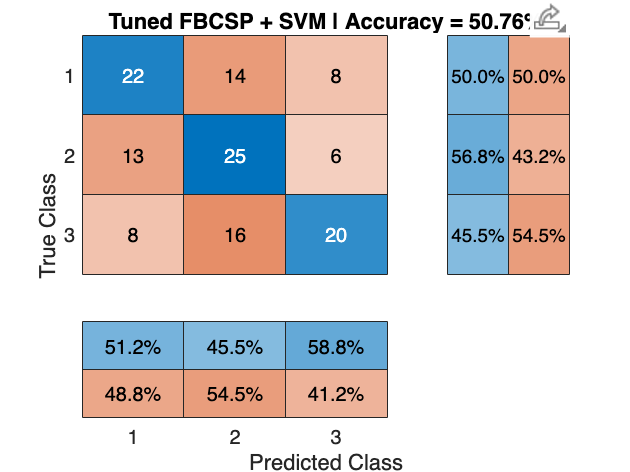


%% Confusion matrix

figure;
confusionchart(y_test, y_pred, ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

title(sprintf('Tuned FBCSP + SVM | Accuracy = %.2f%%', accuracy));

%% Save results and model for robot control

outputPath = fullfile(basePath, 'Outputs', 'Filtered data');

if ~exist(outputPath, 'dir')
    mkdir(outputPath);
end

saveas(gcf, fullfile(outputPath, 'tuned_fbcsp_svm_confusion_matrix.png'));


% Save full result file
save(fullfile(outputPath, 'tuned_fbcsp_svm_results.mat'), ...
    'accuracy', ...
    'bestCVAccuracy', ...
    'bestSettings', ...
    'tuningTable', ...
    'featureScores', ...
    'svmModel', ...
    'y_train', ...
    'y_test', ...
    'y_pred', ...
    'commands', ...
    'bands', ...
    'm', ...
    'sfreq', ...
    'feat_train_all', ...
    'feat_test_all');

% Save model package for robot/control use
save(fullfile(outputPath, 'tuned_fbcsp_svm_model.mat'), ...
    'svmModel', ...
    'bestSettings', ...
    'W_bank', ...
    'bands', ...
    'm', ...
    'sfreq', ...
    'accuracy', ...
    'y_pred', ...
    'commands');

disp("Tuned Filter Bank CSP + SVM results saved successfully.");

Tuned Filter Bank CSP + SVM results saved successfully.


disp("Model package saved for robot control!");

Model package saved for robot control!



%% ================= Helper Functions =================


function X_filt = bandpass_epochs(X, sfreq, lowF, highF)
    % Bandpass filter each channel of each epoch.
    % Keeps EEG activity between lowF and highF Hz.

    [n_channels, n_samples, n_trials] = size(X);
    X_filt = zeros(n_channels, n_samples, n_trials);

    % 4th-order Butterworth bandpass filter
    [b, a] = butter(4, [lowF highF] / (sfreq/2), 'bandpass');

    for t = 1:n_trials
        for ch = 1:n_channels

            signal = double(squeeze(X(ch,:,t)));

            % filtfilt filters forward and backward
            % This avoids phase shift
            X_filt(ch,:,t) = filtfilt(b, a, signal);

        end
    end
end

function W_all = train_multiclass_csp(X_train, y_train, m)
    % One-vs-rest CSP for 3-class classification.
    % It trains:
    % Class 1 vs others
    % Class 2 vs others
    % Class 3 vs others

    classes = unique(y_train);
    W_all = cell(length(classes),1);

    for i = 1:length(classes)

        classLabel = classes(i);

        X_class = X_train(:,:,y_train == classLabel);
        X_rest  = X_train(:,:,y_train ~= classLabel);

        W = train_csp_binary(X_class, X_rest, m);

        W_all{i} = W;

        fprintf("CSP filters trained for class %d vs rest\n", classLabel);
    end
end

function W = train_csp_binary(X1, X2, m)
    % Binary CSP between one class and the rest.
    % CSP finds spatial filters that maximize variance for one group
    % and minimize variance for the other group.

    C1 = average_covariance(X1);
    C2 = average_covariance(X2);

    % Small regularization for numerical stability
    reg = 1e-6 * eye(size(C1));
    C1 = C1 + reg;
    C2 = C2 + reg;

    % Generalized eigenvalue decomposition
    [V, D] = eig(C1, C1 + C2);

    eigenvalues = diag(D);

    % Sort filters by eigenvalues
    [~, idx] = sort(eigenvalues, 'descend');
    V = V(:, idx);

    % Select first m and last m CSP filters
    % If m = 2 and there are 64 channels:
    % selected = [1 2 63 64]
    selected = [1:m, size(V,2)-m+1:size(V,2)];

    % CSP projection matrix
    W = V(:, selected)';
end

function C_avg = average_covariance(X)
    % Computes average normalized covariance matrix across trials.
    % Covariance describes how EEG channels vary together.

    n_trials = size(X,3);
    n_channels = size(X,1);

    C_avg = zeros(n_channels, n_channels);

    for t = 1:n_trials

        trial = double(squeeze(X(:,:,t)));

        % Remove channel-wise mean
        trial = trial - mean(trial, 2);

        % Covariance matrix
        C = trial * trial';

        % Normalize covariance
        C = C / trace(C);

        C_avg = C_avg + C;
    end

    C_avg = C_avg / n_trials;
end

function features = extract_multiclass_csp_features(X, W_all)
    % Applies learned CSP filters to each EEG epoch
    % and extracts log-variance features.

    n_trials = size(X,3);

    sample_feat = extract_csp_features_single_trial(X(:,:,1), W_all);
    n_features = length(sample_feat);

    features = zeros(n_trials, n_features);

    for t = 1:n_trials

        trial = double(squeeze(X(:,:,t)));

        features(t,:) = extract_csp_features_single_trial(trial, W_all);

    end
end

function feat = extract_csp_features_single_trial(trial, W_all)
    % Extracts CSP log-variance features from one EEG epoch.

    trial = double(trial);

    % Remove channel-wise mean
    trial = trial - mean(trial, 2);

    feat = [];

    for i = 1:length(W_all)

        W = W_all{i};

        % Apply CSP spatial filters
        Z = W * trial;

        % Variance represents power of the CSP-filtered signal
        var_z = var(Z, 0, 2);

        % Normalize variance
        var_z = var_z / sum(var_z);

        % Log-variance feature
        log_var = log(var_z);

        feat = [feat; log_var];
    end

    feat = feat';
end

function [rankedIdx, scores] = rank_features(X, y)
    % Feature ranking.
    % First tries fscmrmr.
    % If fscmrmr is unavailable, uses ANOVA F-score ranking.

    if exist('fscmrmr', 'file') == 2

        [rankedIdx, scores] = fscmrmr(X, y);

        rankedIdx = rankedIdx(:)';
        scores = scores(:)';

    else

        warning("fscmrmr not found. Using ANOVA F-score feature ranking instead.");

        n_features = size(X,2);
        classes = unique(y);

        scores = zeros(1, n_features);

        for f = 1:n_features

            feature = X(:,f);
            overallMean = mean(feature);

            ss_between = 0;
            ss_within = 0;

            for c = 1:length(classes)

                classData = feature(y == classes(c));
                classMean = mean(classData);

                ss_between = ss_between + length(classData) * (classMean - overallMean)^2;
                ss_within = ss_within + sum((classData - classMean).^2);

            end

            scores(f) = ss_between / (ss_within + eps);
        end

        [~, rankedIdx] = sort(scores, 'descend');
    end
end

function commands = labels_to_commands(labels)
    % Converts predicted class labels into robot commands.
    % 1 = LEFT
    % 2 = RIGHT
    % 3 = REST

    commands = strings(length(labels), 1);

    for i = 1:length(labels)

        if labels(i) == 1
            commands(i) = "LEFT";
        elseif labels(i) == 2
            commands(i) = "RIGHT";
        elseif labels(i) == 3
            commands(i) = "REST";
        else
            commands(i) = "UNKNOWN";
        end

    end
end